close all; clear; clc;

ft = @(g, delta) fftshift(fft(fftshift(g))) * delta;
ift = @(G, delta_f) ifftshift(ifft(ifftshift(G)))* length(G) * delta_f;


ft2 = @(g, delta) fftshift(fft2(fftshift(g))) * delta^2;
ift2 = @(G, delta_f) ifftshift(ifft2(ifftshift(G))) * (size(G,1)*delta_f^2);


myconv = @(A, B, delta) ift(ft(A, delta) .* ft(B, delta), 1/(length(A)*delta));
myconv2 = @ (A, B, delta) ift2(ft2(A, delta) .* ft2(B, delta), 1/(size(A, 1)*delta));

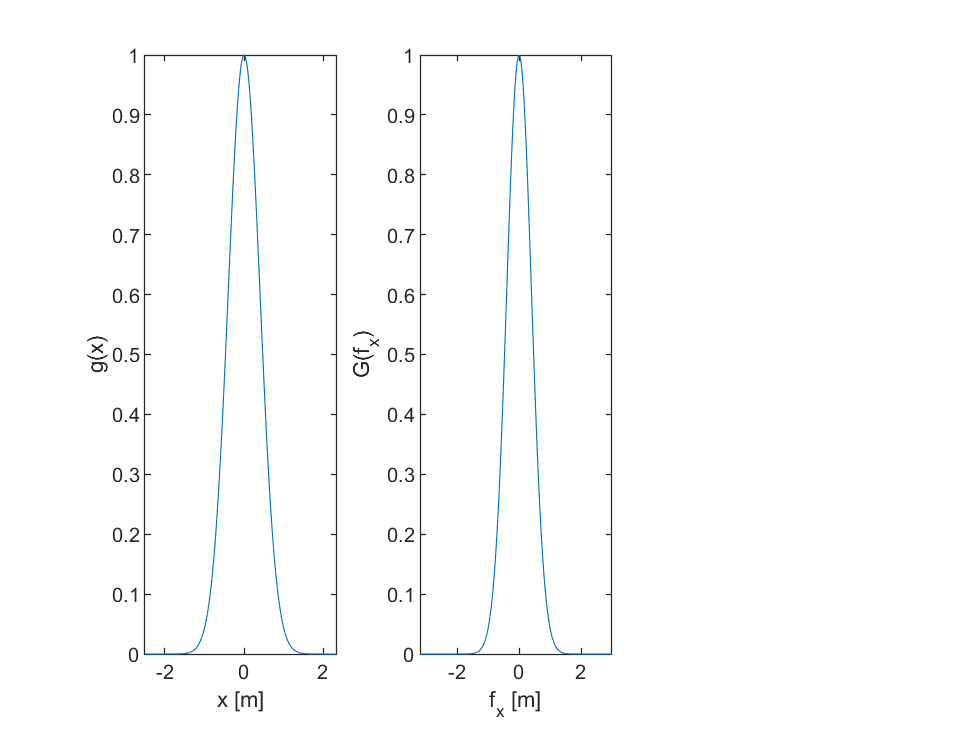


% function values to be used in DFT
L = 5; % spatial extent of the grid
N = 32; % number of samples
delta = L / N; % sample spacing
x = (-N/2 : N/2-1) * delta;
f = (-N/2 : N/2-1) / (N*delta);
a = 1;

% sampled function & its DFT
g_samp = exp(-pi*a*x.^2); % function samples
g_dft = ft(g_samp, delta); % DFT

% analytic function & its continuous FT
M = 1024;
x_cont = linspace(x(1), x(end), M);
f_cont = linspace(f(1), f(end), M);
g_cont = exp(-pi*a*x_cont.^2);
g_ft_cont = exp(-pi*f_cont.^2/a)/a;


figure; 
subplot(131); plot(x_cont, g_cont); xlabel('x [m]'); ylabel('g(x)');
subplot(132); plot(f_cont, g_ft_cont); xlabel('f_x [m]'); ylabel('G(f_x)');

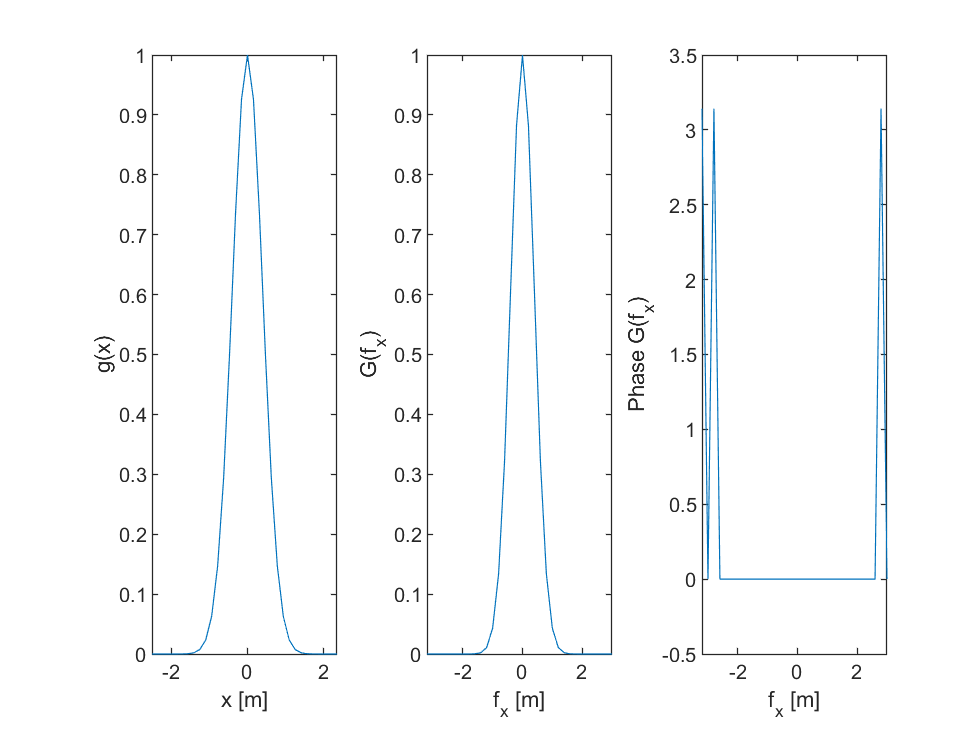


figure; 
subplot(131); plot(x, g_samp); xlabel('x [m]'); ylabel('g(x)');
subplot(132); plot(f, abs(g_dft)); xlabel('f_x [m]'); ylabel('G(f_x)');
subplot(133); plot(f, angle(g_dft)); xlabel('f_x [m]'); ylabel('Phase G(f_x)');

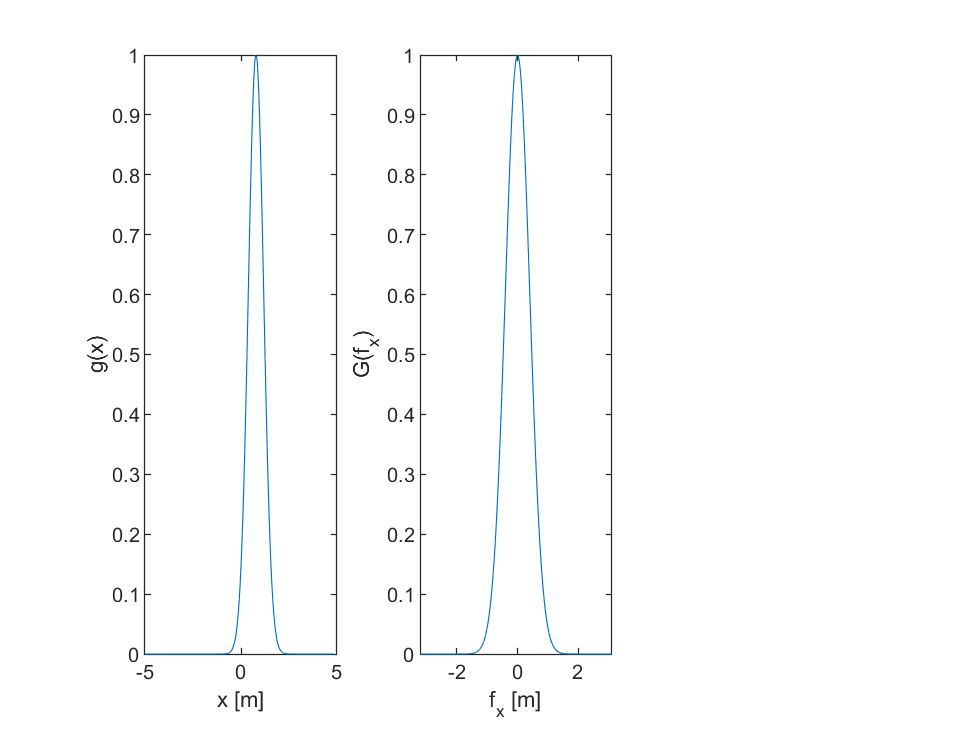

% example_ft_gaussian_shift.m

L = 10; % spatial extent of the grid
N = 64; % number of samples
delta = L / N; % sample spacing
x = (-N/2 : N/2-1) * delta;
x0 = 5*delta;
f = (-N/2 : N/2-1) / (N*delta);
a = 1;
% sampled function & its DFT
g_samp = exp(-pi*a*(x-x0).^2); % function samples
g_dft = ft(g_samp, delta); % DFT
% analytic function & its continuous FT
M = 1024;
x_cont = linspace(x(1), x(end), M);
f_cont = linspace(f(1), f(end), M);
g_cont = exp(-pi*a*(x_cont-x0).^2);
g_ft_cont = exp(-i*2*pi*x0*f_cont).* exp(-pi*f_cont.^2/a)/a;

 
figure; 
subplot(131); plot(x_cont, g_cont); xlabel('x [m]'); ylabel('g(x)');
subplot(132); plot(f_cont, abs(g_ft_cont)); xlabel('f_x [m]'); ylabel('G(f_x)');

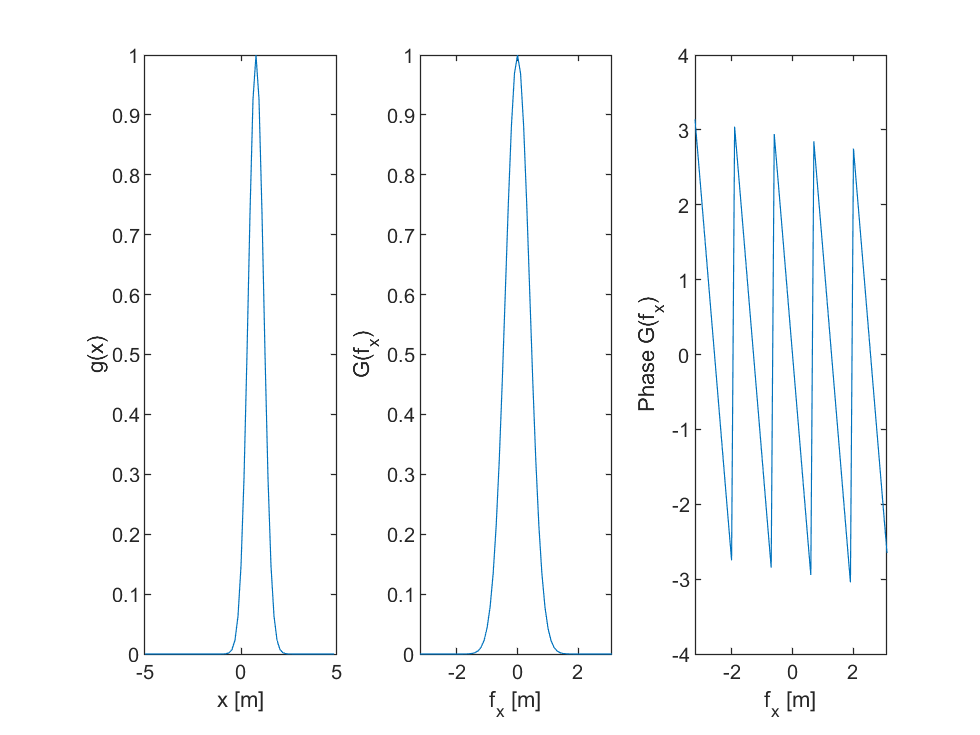


figure; 
subplot(131); plot(x, g_samp); xlabel('x [m]'); ylabel('g(x)');
subplot(132); plot(f, abs(g_dft)); xlabel('f_x [m]'); ylabel('G(f_x)');
subplot(133); plot(f, angle(g_dft)); xlabel('f_x [m]'); ylabel('Phase G(f_x)');

% example_fraunhofer_circ.m
N = 512; % number of grid points per side
L = 7.5e-3; % total size of the grid [m]
d1 = L / N; % source-plane grid spacing [m]
D = 1e-3; % diameter of the aperture [m]
wvl = 1e-6; % optical wavelength [m]
k = 2*pi / wvl;
Dz = 20; % propagation distance [m]

[x1, y1] = meshgrid((-N/2 : N/2-1) * d1);
Uin = circ(x1, y1, D);

'circ' is used in Create Animation of Circle with Timer.

[Uout, x2, y2] = fraunhofer_prop(Uin, wvl, d1, Dz);

% analytic result
Uout_th = exp(i*k/(2*Dz)*(x2.^2+y2.^2)) / (i*wvl*Dz) * D^2*pi/4 .* jinc(D*sqrt(x2.^2+y2.^2)/(wvl*Dz));

function c = corr2_ft(u1, u2, mask, delta)

    N = size(u1, 1);
    c = zeros(N);
    delta_f = 1/(N*delta); % frequency grid spacing [m]
    
    U1 = ft2(u1 .* mask, delta); % DFTs of signals
    U2 = ft2(u2 .* mask, delta);
    U12corr = ift2(conj(U1) .* U2, delta_f);
    
    maskcorr = ift2(abs(ft2(mask, delta)).^2, delta_f)* delta^2;
    idx = logical(maskcorr);
    c(idx) = U12corr(idx) ./ maskcorr(idx) .* mask(idx);
end


function [Uout, x2, y2] = fraunhofer_prop(Uin, wvl, d1, Dz)
    N = size(Uin, 1); % assume square grid
    k = 2*pi / wvl; % optical wavevector
    fX = (-N/2 : N/2-1) / (N*d1);
    % observation-plane coordinates
    [x2, y2] = meshgrid(wvl * Dz * fX);
    clear('fX');
    Uout = exp(i*k/(2*Dz)*(x2.^2+y2.^2)) / (i*wvl*Dz) .* ft2(Uin, d1);
end


function y = rect(x, D)
% function y = rect(x, D)
if nargin == 1, D = 1; end
x = abs(x);
y = double(x<D/2);
y(x == D/2) = 0.5;
end


function y = tri(t)
% function y = tri(t)
t = abs(t);
y = zeros(size(t));
idx = find(t < 1.0);
y(idx) = 1.0 - t(idx);
end



function z = circ(x, y, D)
    % function z = circ(x, y, D)
r = sqrt(x.^2+y.^2);
z = double(r<D/2);
 z(r==D/2) = 0.5;
end


function z = circ(x, y, D)
    % function z = circ(x, y, D)
    r = sqrt(x.^2+y.^2);
    z = double(r<D/2);
    z(r==D/2) = 0.5;
end


function U = fresnel_prop_square_ap(x2, y2, D1, wvl, Dz)
    % function U = fresnel_prop_square_ap(x2, y2, D1, wvl, Dz)
    
    N_F = (D1/2)^2 / (wvl * Dz); % Fresnel number
    % substitutions
    bigX = x2 / sqrt(wvl*Dz);
    bigY = y2 / sqrt(wvl*Dz);
    alpha1 = -sqrt(2) * (sqrt(N_F) + bigX);
    alpha2 = sqrt(2) * (sqrt(N_F) - bigX);
    beta1 = -sqrt(2) * (sqrt(N_F) + bigY);
    beta2 = sqrt(2) * (sqrt(N_F) - bigY);
    % Fresnel sine and cosine integrals
    ca1 = mfun('FresnelC', alpha1);
    sa1 = mfun('FresnelS', alpha1);
    ca2 = mfun('FresnelC', alpha2);
    sa2 = mfun('FresnelS', alpha2);
    cb1 = mfun('FresnelC', beta1);
    sb1 = mfun('FresnelS', beta1);
    cb2 = mfun('FresnelC', beta2);
    sb2 = mfun('FresnelS', beta2);
    % observation-plane field
    U = 1 /(2*i) *((ca2 - ca1) + i * (sa2 - sa1)) .* ((cb2 - cb1) + i * (sb2 - sb1));
end